# Replicating Fig2 with events

And associated supplementals

data_source = SessManager.load_special('Mouse2022');
load(data_source.source_path);
pos_raw = tracesEvents.position(:,1);
time = (1:numel(pos_raw))/20;
pos_norm = (pos_raw - prctile(pos_raw, 5))./(prctile(pos_raw, 95) - prctile(pos_raw, 5))*120; %cm
pos_norm(pos_norm < 0) = 0;
pos_norm(pos_norm > 120) = 120;

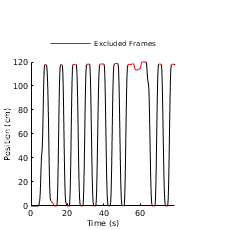

figure;

plot(time, pos_norm, 'k');
opt = DecodeTensor.default_opt; opt.total_length = 120; opt.bin_width = 6;
[~, ~, tr_s, tr_e, ~, ~, ~] = DecodeTensor.new_sel(pos_raw, opt);
bad_y = pos_norm;
for tr_i = 1:numel(tr_s)
    bad_y(tr_s(tr_i):tr_e(tr_i)) = nan;
end
hold on;
h = plot(time, bad_y, 'r');
legend(h, 'Excluded Frames'); legend boxoff; legend location northoutside

xlim([0 79]);
%xlim([0 4030]/20);
%xlim([105.7 169.4]);
%xlim([-516 -453] + 516);

ylabel 'Position (cm)'
xlabel 'Time (s)'

ylim([0 120]);
%line([139 147], [140 140], 'Color', 'r');
%text(149, 140, 'Excluded frames');
%annotation('textbox', [(163.5/150-0.412) 0.75 0.3 0.3], 'String', 'Excluded frames',...
%    'FitBoxToText', 'on', 'FontName', 'Helvetica', 'FontSize', 6, 'LineStyle', 'none');
%annotation('line', [142 147]/150-0.295, [140 140]/150 + 0.038, 'Color', 'r')
%set(gca, 'XTick', []);
%set(gca, 'YTick', []);
%figure_format('boxsize', [3.625 0.77], 'fig_factor', 1.45);
figure_format([1.5 1.5]);
Utils.printto('events_figs/f2_events', 'trajectory.pdf');

## Decoding position demo

data_source = SessManager.load_special('Mouse2022');
opt = DecodeTensor.default_opt;
load(data_source.source_path);
traces = tracesEvents.events_transients;

[~, ~, trial_start, trial_end, trial_dir, ~, ks] =...
    DecodeTensor.new_sel(tracesEvents.position, opt);
within_trial = zeros(size(ks));
trial_start = trial_start(trial_dir==1);
trial_end = trial_end(trial_dir==1);
n_trials = numel(trial_start);
for i = 1:n_trials
    within_trial(trial_start(i):trial_end(i)) = i;
end

time_coord = (1:numel(ks))./opt.samp_freq;
if true
    first_half = (mod(within_trial,2) == 1) & (within_trial ~= 0);
    second_half = (mod(within_trial,2) == 0) & (within_trial ~= 0);
else
    first_half = (within_trial <= n_trials/2) & (within_trial ~= 0);
    second_half = (within_trial > n_trials/2) & (within_trial ~= 0);
end

ks_first_half = ks(first_half);
ks_second_half = ks(second_half);
X_first_half = traces(first_half, :);
X_second_half = traces(second_half, :);
X_first_half_s = shuffle(X_first_half, ks_first_half);
X_second_half_s = shuffle(X_second_half, ks_second_half);

alg = my_algs('ecoclin');
model1 = alg.train(X_first_half, ks_first_half); disp('m1');

m1


model1_s = alg.train(X_first_half_s, ks_first_half); disp('m1s');

m1s


model2 = alg.train(X_second_half, ks_second_half); disp('m2');

m2


model2_s = alg.train(X_second_half_s, ks_second_half); disp('m2s');

m2s



ps_first_half = alg.test(model2, X_first_half);
ps_first_half_s = alg.test(model2_s, X_first_half_s);
ps_first_half_d = alg.test(model2_s, X_first_half);
ps_second_half = alg.test(model1, X_second_half);
ps_second_half_s = alg.test(model1_s, X_second_half_s);
ps_second_half_d = alg.test(model1_s, X_second_half);

me_ = @(k,p) mean(abs(ceil(k(:)/2)-ceil(p(:)/2))).*opt.bin_width;
mse_ = @(k,p) mean((ceil(k(:)/2)-ceil(p(:)/2)).^2).*opt.bin_width.^2;
fprintf('Mean error: unsh: %f, sh: %f\n',  me_(ks_first_half, ps_first_half),...
    me_(ks_first_half, ps_first_half_s));

Mean error: unsh: 2.880467, sh: 0.944551


fprintf('Mean error: unsh: %f, sh: %f\n',  me_(ks_second_half, ps_second_half),...
    me_(ks_second_half, ps_second_half_s));

Mean error: unsh: 2.531590, sh: 1.035458




tr_track = within_trial(first_half|second_half);

ks_ = ks(within_trial~=0);
ps_(first_half) = ps_first_half;
ps_(second_half) = ps_second_half;
ps_ = ps_(within_trial~=0)';
ps_s_(first_half) = ps_first_half_s;
ps_s_(second_half) = ps_second_half_s;
ps_s_ = ps_s_(within_trial~=0)';

for i = 1:max(tr_track)
    tr_err(i) = me_(ks_(tr_track==i), ps_(tr_track==i));
    tr_err_s(i) = me_(ks_(tr_track==i), ps_s_(tr_track==i));
end

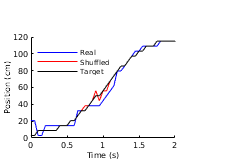

figure;
t = (1:numel(ks_first_half))./opt.samp_freq;
t_start = 83.5 + 2.05; %which to show
t_end = 83.5 + 4.05;%90;

hold on;
h(1) = plot(t - t_start, (ceil(ps_first_half/2) - 0.5)*opt.bin_width, '-b');
h(2) = plot(t - t_start, (ceil(ps_first_half_s/2) - 0.5)*opt.bin_width, '-r');
h(3) = plot(t - t_start, (ceil(ks_first_half/2) - 0.5)*opt.bin_width, '-k');

trial_boundaries = (find(diff(within_trial(first_half))>0)+0.5)./opt.samp_freq - t_start;
for i = 1:numel(trial_boundaries)
    x_ = trial_boundaries(i);
    line([x_ x_], ylim, 'Color', 'k', 'LineStyle', '--');
end
xlim([t_start t_end] - t_start);
ylim([-Inf Inf]);
xlabel 'Time (s)';
ylabel 'Position (cm)';
legend(h, 'Real', 'Shuffled', 'Target');
legend boxoff
legend location best
figure_format('boxsize', [1 0.7]*1.5);% box on;
Utils.printto('events_figs/f2_events', 'decoding_demo.pdf');

## Confusion matrix

res = confusion_mat_runner(69);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 16).
Elapsed time is 310.254711 seconds.


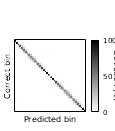

nt = res(1).num_trials;
C_pct = cat(3, res.C)/nt*100;
C_s_pct = cat(3, res.C_s)/nt*100;

figure;
PanelGenerator.plot_confusion(C_pct, 'Confusion (%)');
colormap gray
colormap(flipud(colormap(gca)));
Utils.printto('events_figs/f2_events', 'confusion_unshuffled.pdf');

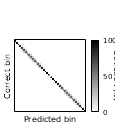


figure;
PanelGenerator.plot_confusion(C_s_pct, 'Confusion (%)');
colormap gray
colormap(flipud(colormap(gca)));
Utils.printto('events_figs/f2_events', 'confusion_shuffled.pdf');

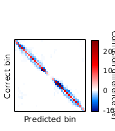


figure;
PanelGenerator.plot_confusion(C_s_pct - C_pct, 'Confusion difference (%)', false);
colormap(bluewhitered);
Utils.printto('events_figs/f2_events', 'confusion_diff.pdf');

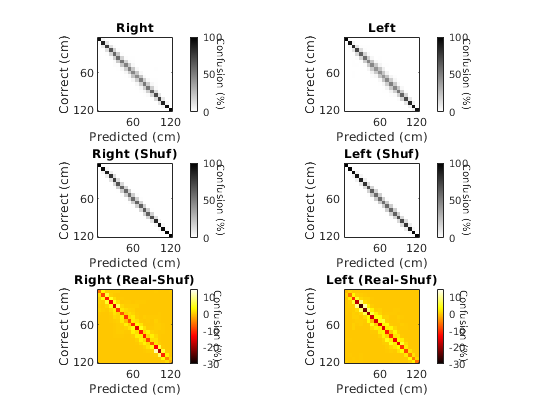

figure;

subplot(3,2,1);
plot_confusion(C_pct(1:20,1:20,:), 'Confusion (%)');
colormap gray
colormap(flipud(colormap(gca)));
title 'Right'

subplot(3,2,2);
plot_confusion(C_pct(21:40,21:40,:), 'Confusion (%)');
colormap gray
colormap(flipud(colormap(gca)));
title 'Left'

subplot(3,2,3);
plot_confusion(C_s_pct(1:20,1:20,:), 'Confusion (%)');
colormap gray
colormap(flipud(colormap(gca)));
title 'Right (Shuf)'

subplot(3,2,4);
plot_confusion(C_s_pct(21:40,21:40,:), 'Confusion (%)');
colormap gray
colormap(flipud(colormap(gca)));
title 'Left (Shuf)'

cm = 'hot';%hot
sp = subplot(3,2,5);
plot_confusion(C_pct(1:20,1:20,:)-C_s_pct(1:20,1:20,:), 'Confusion (%)', false, [-30 15]);
colormap(sp, cm);
title 'Right (Real-Shuf)'

sp = subplot(3,2,6);
plot_confusion(C_pct(21:40,21:40,:)-C_s_pct(21:40,21:40,:), 'Confusion (%)', false, [-30 15]);
colormap(sp, cm);
title 'Left (Real-Shuf)'

Utils.printto('events_figs/f2_events', 'confusion_all_split.pdf');

## Decoding curves

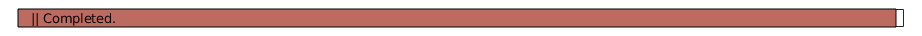

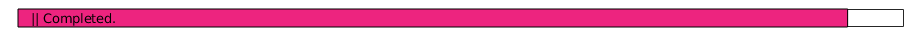

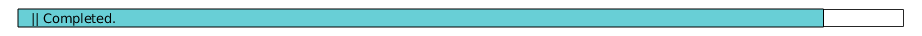

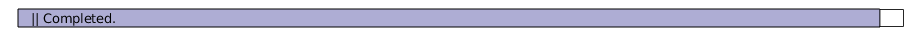

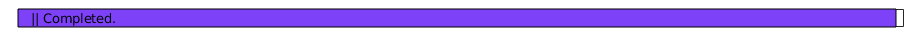

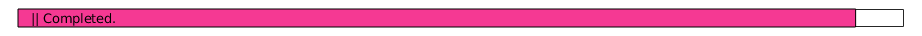

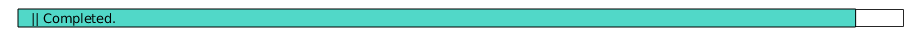

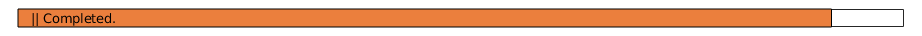

Unshuf R^2: -519.634606 - 0.999168, median: 0.996485
Shuf R^2: -1021.302369 - 0.998336, median: 0.983625
Diag R^2: -609.802187 - 0.999345, median: 0.994151
Unshuf (exp) R^2: -18.731794 - 0.999079, median: 0.996684
Shuf (exp) R^2: -32.908018 - 0.998339, median: 0.982250
Diag (exp) R^2: -20.255569 - 0.999299, median: 0.186787


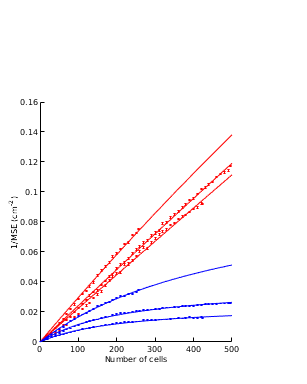

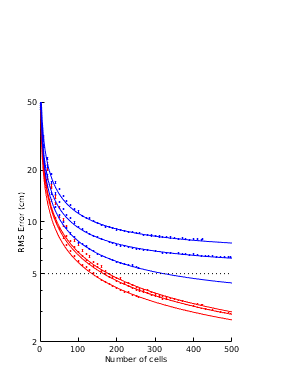

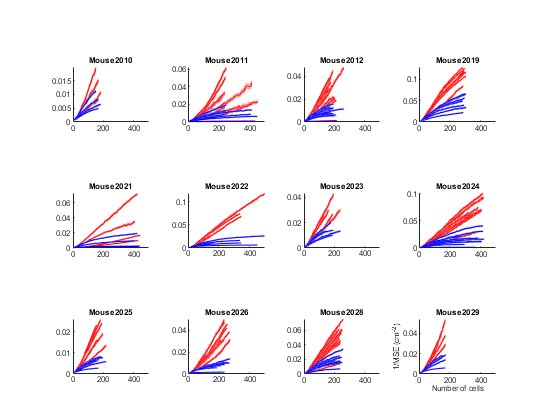

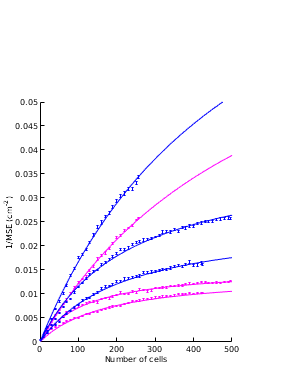

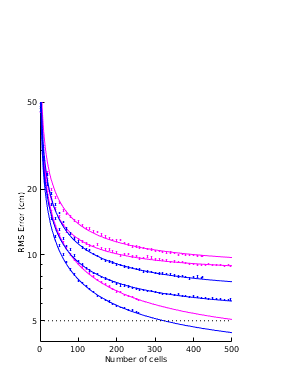

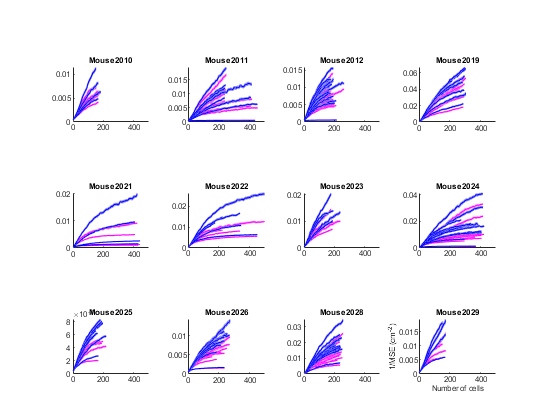

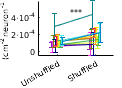

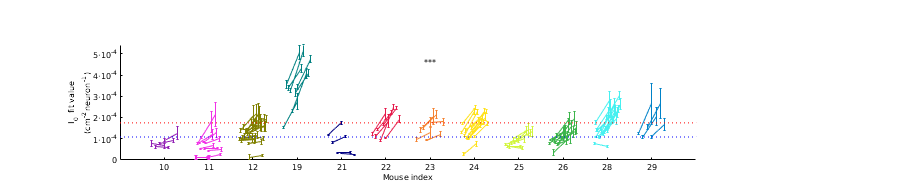

Value of I_0 across mice: 1.169625e-04 +- 4.474618e-05 (95% conf)
Value of I_0 (shuf) across mice: 1.757694e-04 +- 7.265583e-05 (95% conf)


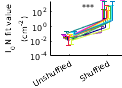

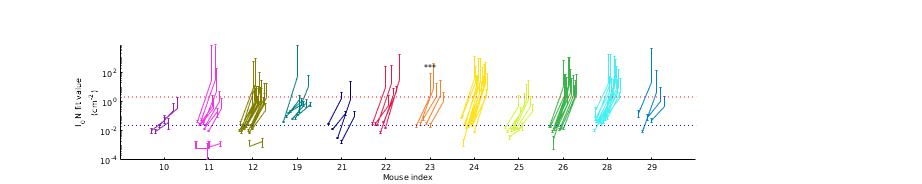

Value of I_0N across mice: 3.783978e-02 +- 3.607748e-02 (95% conf)
Value of I_0N (shuf) across mice: 5.865950e+00 +- 1.391205e+03 (95% conf)
Value of log(I_0N), postfunc: 8.755391e-03 - 5.527068e-02, mid: 2.199810e-02
Value of log(I_0N) (shuf), postfunc: 9.775825e-22 - 1.990584e+21, mid: 1.394977e+00


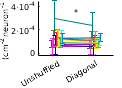

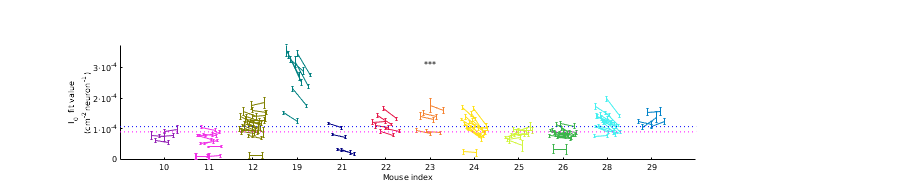

Value of I_0 across mice: 1.169625e-04 +- 4.474618e-05 (95% conf)
Value of I_0 (diag) across mice: 1.030254e-04 +- 3.632862e-05 (95% conf)


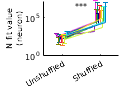

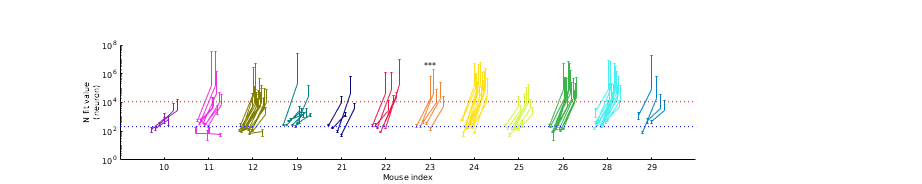

Value of N across mice: 2.899887e+02 +- 2.565008e+02 (95% conf)
Value of N (shuf) across mice: 2.933502e+04 +- 6.130257e+06 (95% conf)
Value of log(N), postfunc: 1.161679e+02 - 4.245479e+02, mid: 2.220784e+02
Value of log(N) (shuf), postfunc: 6.914719e-18 - 1.387784e+25, mid: 9.795985e+03


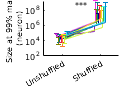

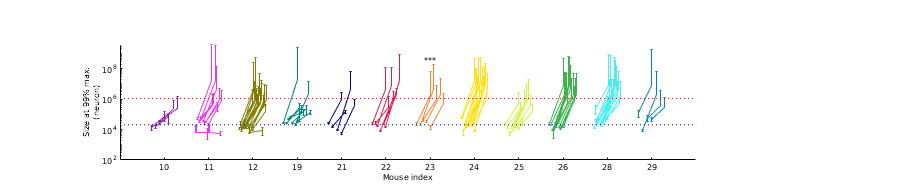

Value of 99N across mice: 2.870889e+04 +- 2.539357e+04 (95% conf)
Value of 99N (shuf) across mice: 2.904167e+06 +- 6.068955e+08 (95% conf)
Value of log(99N), postfunc: 1.150062e+04 - 4.203024e+04, mid: 2.198577e+04
Value of log(99N) (shuf), postfunc: 6.845572e-16 - 1.373906e+27, mid: 9.698026e+05


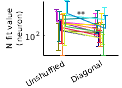

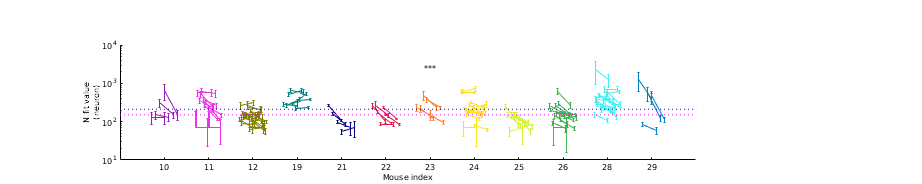

Value of N across mice: 2.899887e+02 +- 2.565008e+02 (95% conf)
Value of N (diag) across mice: 1.873552e+02 +- 1.180809e+02 (95% conf)
Value of log(N), postfunc: 1.161679e+02 - 4.245479e+02, mid: 2.220784e+02
Value of log(N) (diag), postfunc: 8.509152e+01 - 2.512377e+02, mid: 1.462129e+02


PanelGenerator.decoding_curves(true, true);

function plot_confusion(C_pct, cbar_label, clim_exists, clim)
%Plot a confusion matrix, or difference between confusion
%matrices.
%Inputs:
%   C_pct: square confusion matrix where elements are percentages
%   cbar_label: string to display as a label to the colorbar
%   clim_exists (optional, default true): whether or not to
%   show the color range from 0 to 100 rather than min to max
nb = size(C_pct, 1);
if ~exist('clim_exists', 'var') || clim_exists
    imagesc(squeeze(mean(C_pct,3)), [0 100]);
else
    imagesc(squeeze(mean(C_pct,3)), clim);
end
xlabel 'Predicted (cm)'
ylabel 'Correct (cm)'
axis equal;
xlim([1 nb] + [-0.5 0.5]);
set(gca, 'XTick', [0, nb/2, nb]);
set(gca, 'YTick', [0, nb/2, nb]);
set(gca, 'XTickLabel', {'0', '60', '120'});%{'60 cm', '120 cm', '60 cm', '120 cm'});
set(gca, 'YTickLabel', {'0', '60', '120'});%{'60 cm', '120 cm', '60 cm', '120 cm'});
%line([nb nb]/2+0.5, ylim, 'Color', 'w');
%line(xlim, [nb nb]/2+0.5, 'Color', 'w');
h_ = colorbar; ylabel(h_, cbar_label, 'Rotation', 270);
%Utils.specific_format('confusion');
end